# Anisotropic, viscoelastic SH-wave propagation at Campi Flegrei

CODE for the simulation of SH waves in 2D for an anisotropic viscoelastic medium. Reference publication: [Carcione and Cavallini 1996](https://library.seg.org/doi/abs/10.1190/1.1443792) and, obviously, Carcione (2014) also known as: Carcione, J. M. (2007). Wave fields in real media: Wave propagation in anisotropic, anelastic, porous and electromagnetic media: Handbook of geophysical exploration, seismic exploration. *Handbook of Geophysical Exploration: Seismic Exploration*, *38*.

Translated from the Fortran code.

clear
close all
clc

## INPUTS

Choose between isotropic (1), effective anisotropic (2) or scattering simulations (3)

chooseModel                         =   1;

Define velocity fluctuations

rmsVelocityFluctuations             =   0.07;
correlationLength                   =   2;

## Starting material properties

Setting up velocities. You can follow Heap if setting from rock physics e.g., V0=sqrt(4.5*10^9/2500)/1000=1.34 km/s. The ideal is to relate it to actual stiffness parameters so transform them always - easy in the isotropic case.

if chooseModel ==  1
    V0                              =   sqrt(2.25*10^10/2500)/1000;
else

More difficult in the ansotropic case.

    V0_SN                           =   2;
    V0_WE                           =   4;
end

Average material properties - density and attenuation.

rhoAverage                          =   2500;
rhoScattering                       =   2500;    
Q2Average                           =   100;
Q4Average                           =   100;
Q2Scattering                        =   100;
Q4Scattering                        =   100;

## Time inputs

See calculations at the start. They are all in seconds - this simulation is for 8 s. Start from the origin time in your SAC files (tData). For the frequency inputs see calculations at the start - they are all in Hz. The relaxation frequency and time define where you expect absorption to happen: here, set to 10 Hz so that there is small effect.

dt                                  =   .0005;
numberStep                          =   16000;
tData                               =   50;
Time                                =   tData+0:dt:tData+(numberStep-1)*dt;
nFrame                              =   100; % Visualizes every
fRelaxationTimes                    =   10;
relaxationTime                      =   1/(2*pi*fRelaxationTimes);

## Spatial inputs

Set up the model nodes. Give the origin in UTM WGS84 as well as the number of nodes and vectors in the 2D space.

dx                                  =   20;
dz                                  =   20;
origin                              =   [418100 4512100];
spatialSampling                     =   1/100;
nodesX                              =   1000;
nodesZ                              =   1000;
X                                   =   origin(1) + (dx:dx:nodesX*dx);
Y                                   =   origin(2) + (dz:dz:nodesZ*dz);
[XX,YY]                             =   ndgrid(X,Y);

Set anisotropic zone for case 3. Creat the volume you want to set as scattering by hand. Also add the Rim.

if chooseModel ==  3
    
    scatterInitialX                 =   nodesX/2 - 0/dx;
    scatterFinishX                  =   nodesX/2 - 0/dx;
    scatterLengthX                  =   length(scatterInitialX:scatterFinishX);
    
    scatterInitialZ                 =   nodesZ/2-0/dz;
    scatterFinishZ                  =   nodesZ/2 - 0/dz;
    scatterLengthZ                  =   length(scatterInitialZ:scatterFinishZ);
    
    centerRimX                      =   nodesX/2+600/dx;
    centerRimZ                      =   nodesZ/2-4000/dz;
    scatterVectorX                  =   -nodesX/2+1:nodesX/2;
    scatterVectorZ                  =   -nodesZ/2+1:nodesZ/2;
    R=zeros(nodesX,nodesZ);
    for i=1:length(scatterVectorX)
        for j=1:length(scatterVectorZ)
            R(i,j)                  =...
                sqrt((scatterVectorX(i)-centerRimX)^2+(scatterVectorZ(j)-centerRimZ)^2);
        end
    end
    rim                             =   0/dx;
    R1                              =   R>rim;

end

## Definition of the velocity fluctuations in space

rho                                 =   rhoAverage*ones(nodesX,nodesZ);
spatialWavenumber                   =   zeros(nodesZ);
spatialWavenumber(1,:)              =...
    spatialSampling:spatialSampling:nodesZ/100;
spatialWavenumber(:,1)              =...
    spatialSampling:spatialSampling:nodesZ/100;

m1                                  =   zeros(nodesZ,1);
for i = 2:nodesZ
    m1(i)=spatialSampling*i;
    spatialWavenumber(2:end,i)      =...
        sqrt(m1(i).^2+spatialWavenumber(2:end,1).^2);
end

The power spectral density function is exponential.

Pexp                                =...
    4*pi*rmsVelocityFluctuations^2*correlationLength^2./...
    (1+correlationLength^2*spatialWavenumber.^2).^2;
phase                               =...
    2*pi.*rand(size(spatialWavenumber));
ePhase                              =   (exp(1i*phase));

Velocity fluctuations respect to the average.

csi                                 =...
    1/4/pi^2*abs(fft2(sqrt(Pexp).*ePhase));
csi                                 =   csi(1:nodesX,1:nodesZ);
csi                                 =   csi-mean(csi(:));

Need to deal with both isotropic and anisotropic cases.

if chooseModel ==  1
    csi_h                           =   V0*(1+csi);
else
    csi_SN                          =   V0_SN*(1+csi);
    csi_WE                          =   V0_WE*(1+csi);
end

## Definition of additional material properties - stiffness coefficients c44, c66,c46

if chooseModel == 1
    
    c44                             =   rhoAverage.*(csi_h*1000).^2;
    c66                             =   rhoAverage.*(csi_h*1000).^2;
    c46                             =   zeros(nodesX,nodesZ);
     
elseif chooseModel==2
    
    c44                             =   rhoAverage.*(csi_WE*1000).^2;
    c66                             =   rhoAverage.*(csi_SN*1000).^2;
    c46                             =   -1000000000*ones(nodesX,nodesZ);

elseif chooseModel==3
    

Need to distinguish between background and high-scattering media


    c44Average                      =   rhoAverage.*(csi_WE*1000).^2;
    c44Scattering                   =   rhoScattering.*(csi_WE*1000).^2;
    c66Average                      =   rhoAverage.*(csi_SN*1000).^2;
    c66Scattering                   =   rhoScattering.*(csi_SN*1000).^2;
    c46Average                      =   -0.5*sqrt(c44Scattering*c66Scattering);
    c46Scattering                   =   0.5*sqrt(c44Scattering*c66Scattering);

end

Absorbing boundaries parameters.

absorbingCoefficient                =   1;
nab                                 =   120;
sab1(1:nab,1)                       =   absorbingCoefficient.^(nab:-1:1);
sabTop                              =   repmat(sab1,1,nodesZ);
sabBottom                           =   flipud(repmat(sab1,1,nodesZ));
sabRight                            =   flipud(repmat(sab1,1,nodesX))';
sabLeft                             =   repmat(sab1,1,nodesX)';

## Update field variables

For the proper definition of each parameter look at the corresponding publication.

ts2Average                          =...
    (relaxationTime/Q2Average)*(sqrt(Q2Average*Q2Average+1)-1);
te2Average                          =...
    (relaxationTime/Q2Average)*(sqrt(Q2Average*Q2Average+1)+1);
phi2Average                         =   1/te2Average-1/ts2Average;
ts4Average                          =...
    (relaxationTime/Q4Average)*(sqrt(Q4Average*Q4Average+1)-1);
te4Average                          =...
    (relaxationTime/Q4Average)*(sqrt(Q4Average*Q4Average+1)+1);
phi4Average                         =   1/te4Average-1/ts4Average;
ts2Scattering                       =...
    (relaxationTime/Q2Scattering)*(sqrt(Q2Scattering*Q2Scattering+1)-1);
te2Scattering                       =...
    (relaxationTime/Q2Scattering)*(sqrt(Q2Scattering*Q2Scattering+1)+1);
phi2Scattering                      =   1/te2Scattering-1/ts2Scattering;
ts4Scattering                       =...
    (relaxationTime/Q4Scattering)*(sqrt(Q4Scattering*Q4Scattering+1)-1);
te4Scattering                       =...
    (relaxationTime/Q4Scattering)*(sqrt(Q4Scattering*Q4Scattering+1)+1);
phi4Scattering                      =   1/te4Scattering-1/ts4Scattering;

ts2                                 =   ts2Average*ones(nodesX,nodesZ);
phi2                                =   phi2Average*ones(nodesX,nodesZ);
ts4                                 =   ts4Average*ones(nodesX,nodesZ);
phi4                                =   phi4Average*ones(nodesX,nodesZ);

if chooseModel == 3

Here we change the characteristics of the high-scattering areas. 

    c44                             =   c44Average*ones(nodesX,nodesZ);
    c44(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        c44Scattering*ones(scatterLengthX,scatterLengthZ);
    
    c66                             =   c66Average*ones(nodesX,nodesZ);
    c66(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        c66Scattering*ones(scatterLengthX,scatterLengthZ);
    
    c46                             =   c46Average*ones(nodesX,nodesZ);
    c46(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        c46Scattering*ones(scatterLengthX,scatterLengthZ);
    
    rho(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        rhoSCattering*ones(scatterLengthX,scatterLengthZ);
    
    ts2(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        ts2Scattering*ones(scatterLengthX,scatterLengthZ);
    phi2(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        phi2Scattering*ones(scatterLengthX,scatterLengthZ);
    ts4(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        ts4Scattering*ones(scatterLengthX,scatterLengthZ);
    phi4(scatterInitialX:scatterFinishX,scatterInitialZ:scatterFinishZ)=...
        phi4Scattering*ones(scatterLengthX,scatterLengthZ);
    
    ts2(R1)                         =   ts2Scattering;
    phi2(R1)                        =   phi2Scattering;
    ts4(R1)                         =   ts4Scattering;
    phi4(R1)                        =   phi4Scattering;

end

Field variable to update displacement (u, u2):

- e4 and e6 strain components;

- s4 and s6 stress components;

- e23 and e12 memory variables

u2                                  =   zeros(nodesX,nodesZ);
u                                   =   zeros(nodesX,nodesZ);
s4                                  =   zeros(nodesX,nodesZ);
s6                                  =   zeros(nodesX,nodesZ);
e23                                 =   zeros(nodesX,nodesZ);
e12                                 =   zeros(nodesX,nodesZ);


## Setting up figure for the velocity variations

chosenCMap                          =   flipud(inferno);
sz                                  =   20;
figure('Name',...
    'Velocity fluctuations',...
    'NumberTitle','off','Position',[10 10 2000 900]);
if chooseModel == 1
    hn                                  =   pcolor(XX,YY,csi_h);
else
    hn                                  =   surf(XX,YY,csi_SN);

end
hn.EdgeColor                        =   'none';
hn.FaceColor                        =   'interp';

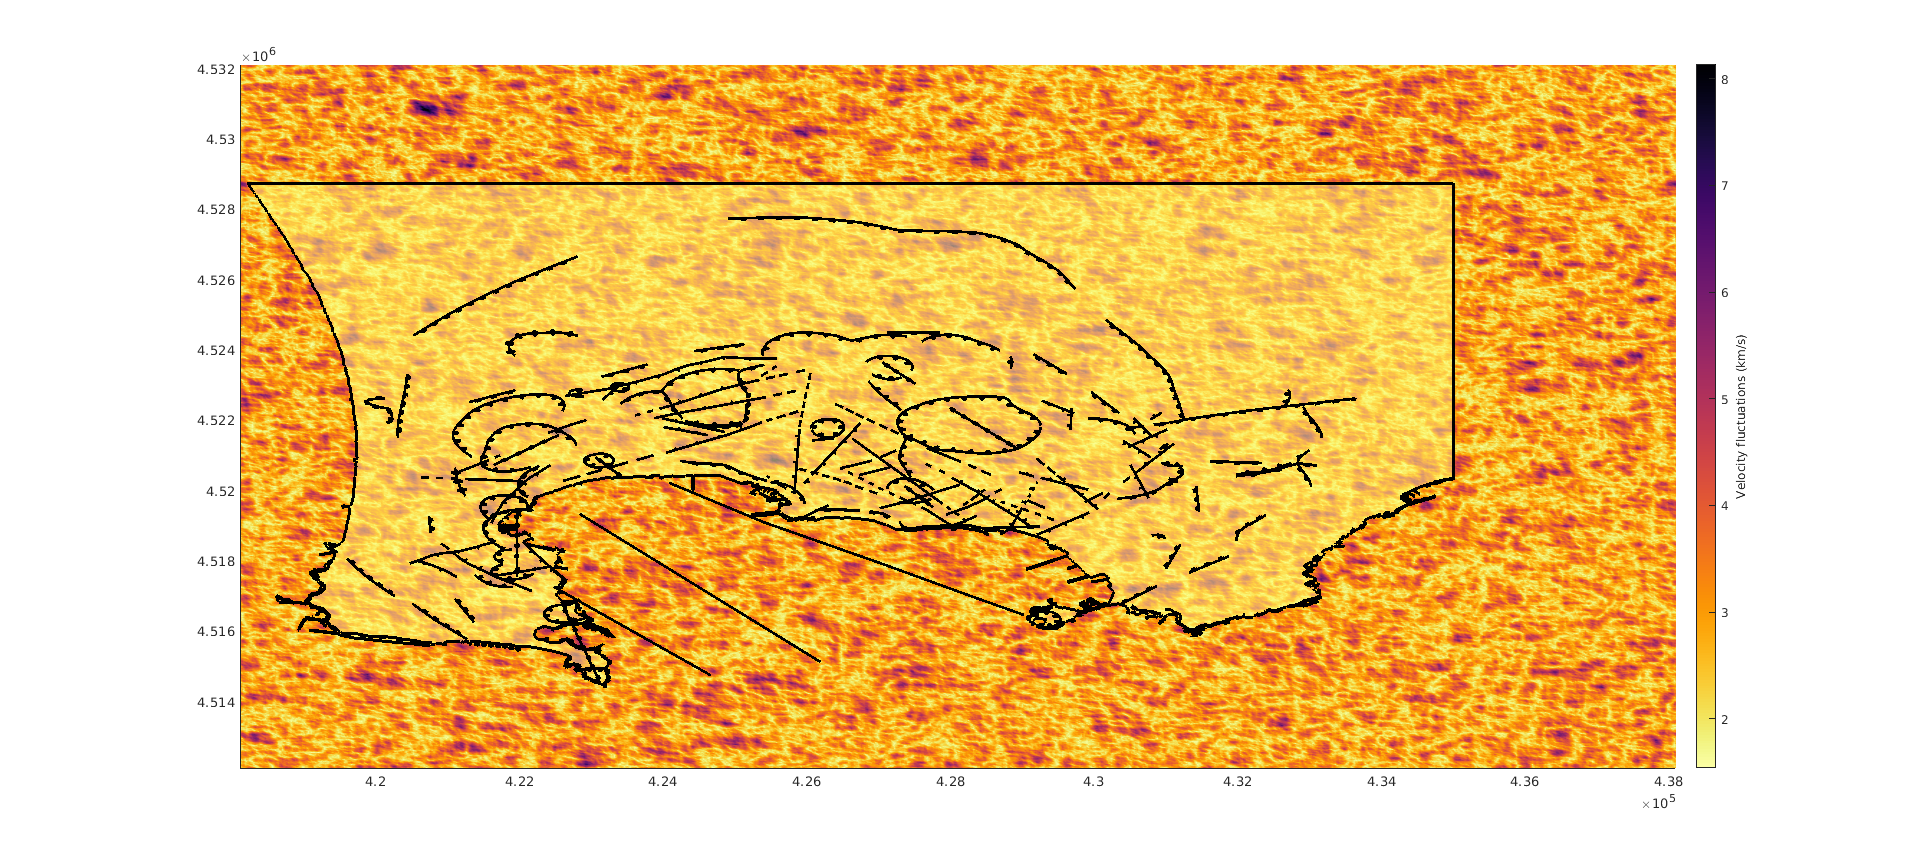

colormap(chosenCMap);
c                                   =   colorbar;
c.Label.String                      =   'Velocity fluctuations (km/s)';
view(0,90)
hold on

C = shaperead('COSs.shp');
mapshow(C,'LineWidth',2,'FaceAlpha',0.5);

Faults= shaperead('FAULTS.shp');
mapshow(Faults,'Color', 'black','LineWidth',2)


xLimits=[418000 434000];
yLimits=[4514000 4528000];

%setDefaultsImagePrint(xLimits,yLimits,sz)
hold off
nameFigure                          =...
    cat(2,'Velocity_fluctuations_',num2str(rmsVelocityFluctuations),...
    '_',num2str(correlationLength),'.tiff');
print(nameFigure,'-dtiff','-r300');


## Source and receiver locations - energy

Here you need to insert the coordinates of the source in degrees

SN                                  =   40 + 49.50/60;
WE                                  =   14 + 9.02/60;
[Es,Ns,~]                           =   deg2utm(SN,WE);
ix                                  =   floor((Es-origin(1))/dx);
iz                                  =   floor((Ns-origin(2))/dz);

Hre you get the coordinates of the stations.

filename                            =   'stazioni_151007.txt';
delimiterIn                         =   ' ';
headerlinesIn                       =   0;
A                                   =...
    importdata(filename,delimiterIn,headerlinesIn);
stazioni                            =   A.data;
namest                              =   A.textdata;
SN                                  =   stazioni(:,1)+stazioni(:,2)/60;
WE                                  =   stazioni(:,3)+stazioni(:,4)/60;
latlong                             =   [SN,WE];
[Er,Nr,Zone]                        =   deg2utm(latlong(:,1),latlong(:,2));
rx                                  =   floor(Er-origin(1))/dx;
rz                                  =   floor(Nr-origin(2))/dz;

Source signaturefrom Choy and Boatwright (1995) - Velocity is: V = Amp (counts) * AonD (volts)/counts / Gain * Sensitivity (volts/m*s).

If 1.58997E-06 (V/counts) / (1 * 1500 (V/m/s)) then: Amp = V/(AonD)*Gain*Sensitivity = V / 1.58997E-06* 1500.

fSource                             =   1;
rhoSource                           =   2500;
M                                   =   2.7;
E                                   =...
    10^(4.4 + 1.5 * M)/fSource^2/rhoSource*dt^3;
rate                                =   numberStep/nFrame;
conversion                          =   1500/ 1.58997E-09;
E                                   =   E*conversion;
Amp                                 =   sqrt(E);

Source wavelet - now using Morlet

dt2=dt/2;
[f,nw2]=morlet1(fSource,dt2);
nw=nw2/2;

Set up amplitudes for seismograms

AmpTime1                            =   zeros(numberStep,1);
AmpTime2                            =   zeros(numberStep,1);
AmpTime3                            =   zeros(numberStep,1);
AmpTime4                            =   zeros(numberStep,1);
AmpTime5                            =   zeros(numberStep,1);
AmpTime6                            =   zeros(numberStep,1);
AmpTime7                            =   zeros(numberStep,1);
AmpTime8                            =   zeros(numberStep,1);
AmpTime9                            =   zeros(numberStep,1);

## Set up wavefield and seismograms figure

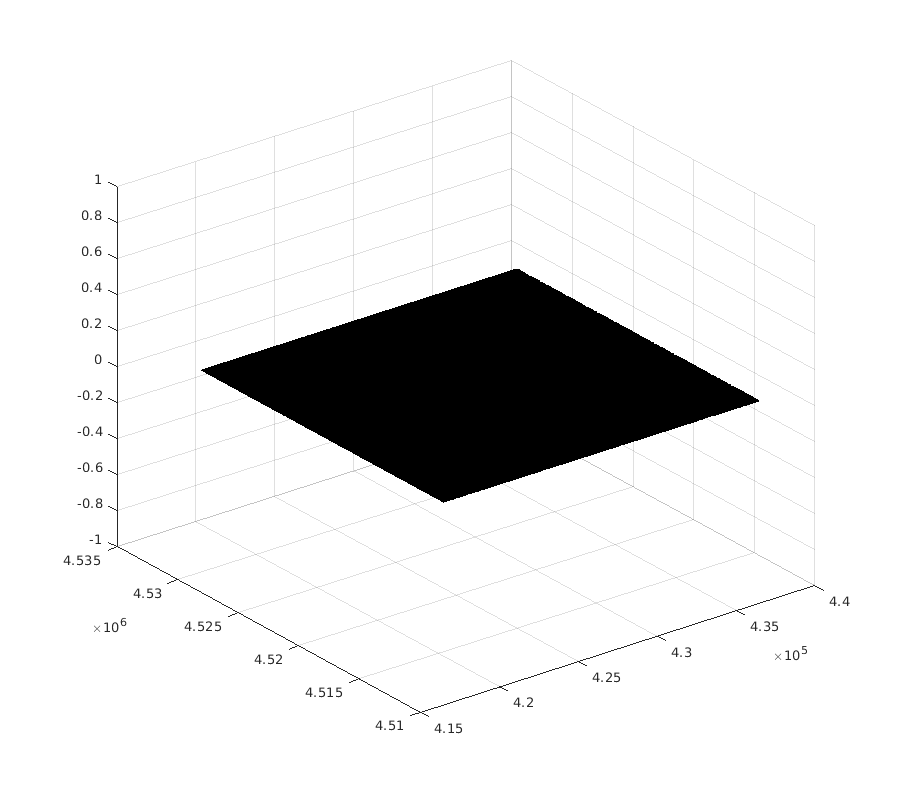

figureWavefield                     =   figure('Name',...
    'Wavefield evolution','NumberTitle','off','Position',[1,200,900,800]);
panelWavefield                      =   surf(XX,YY,u2);
colormap(chosenCMap)
hold on


if chooseModel==3

Plotting for the scattering case.

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


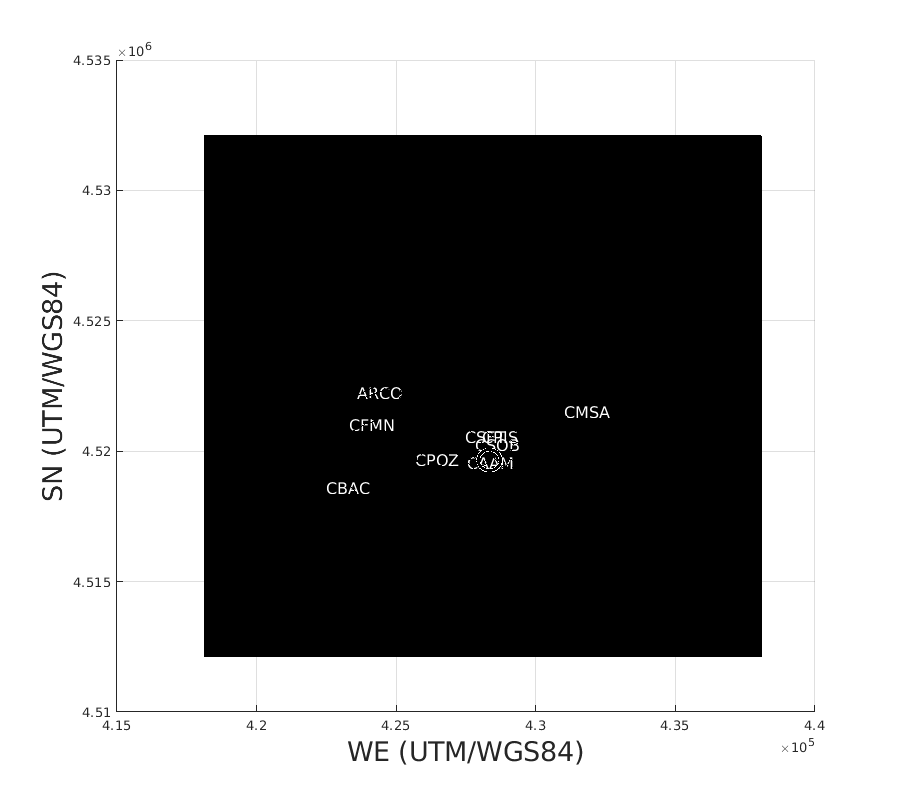

    plot([origin(1)+scatterInitialX*dx origin(1)+scatterInitialX*dx],...
        [origin(2)+scatterInitialZ*dz origin(2)+scatterFinishZ*dz],'LineWidth',...
        2,'Color',[.5 .5 .5]);
    plot([origin(1)+scatterFinishX*dx origin(1)+scatterFinishX*dx],...
        [origin(2)+scatterInitialZ*dz origin(2)+scatterFinishZ*dz],'LineWidth',...
        2,'Color',[.5 .5 .5]);
    plot([origin(1)+scatterInitialX*dx origin(1)+scatterFinishX*dx],...
        [origin(2)+scatterInitialZ*dz origin(2)+scatterInitialZ*dz],'LineWidth',...
        2,'Color',[.5 .5 .5]);
    plot([origin(1)+scatterInitialX*dx origin(1)+scatterFinishX*dx],...
        [origin(2)+scatterFinishZ*dz origin(2)+scatterFinishZ*dz],'LineWidth',...
        2,'Color',[.5 .5 .5]);  
end

light('Position',[0 0 0],'Style','infinite');
view(0,90)
lR                                  =   200;

for i=1:length(rx)
    rectangle('Position',[origin(1)+rx(i)*dx origin(2)+rz(i)*dz lR lR],...
        'FaceColor',[0 0 0])
    text(origin(1)+rx(i)*dx,origin(2)+rz(i)*dz+2*lR,namest{i},...
        'FontSize',12,'Color',[1 1 1])
end

viscircles([origin(1)+ix*dx origin(2)+iz*dz],400,'Color',[0 0 0])
mapshow(C,'FaceAlpha',0);
mapshow(Faults,'Color', 'black')

xlabel('WE (UTM/WGS84)','FontWeight','bold','FontSize',20)
ylabel('SN (UTM/WGS84)','FontWeight','bold','FontSize',20)

hold off

Set the data source for plotting.

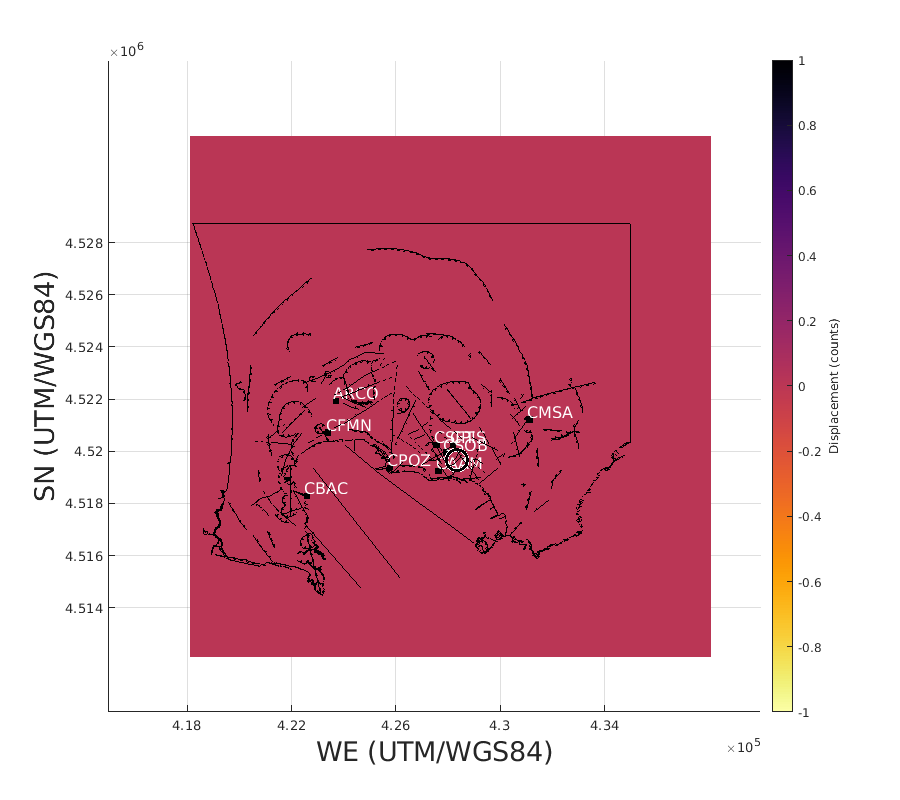

set(panelWavefield,'xdatasource','XX',...
    'ydatasource','YY',...
    'zdatasource','u2')
set(panelWavefield,'FaceLighting','phong','FaceColor','interp',...
    'AmbientStrength',1,'SpecularStrength',1,...
    'DiffuseStrength',0.9,'SpecularColorReflectance',1,...
    'SpecularExponent',10,'FaceAlpha',1, 'linestyle','none')
%setDefaultsImagePrint(xLimits,yLimits,sz)

c                                   =   colorbar;
c.Label.String                      =   'Displacement (counts)';

Set plot wavefield

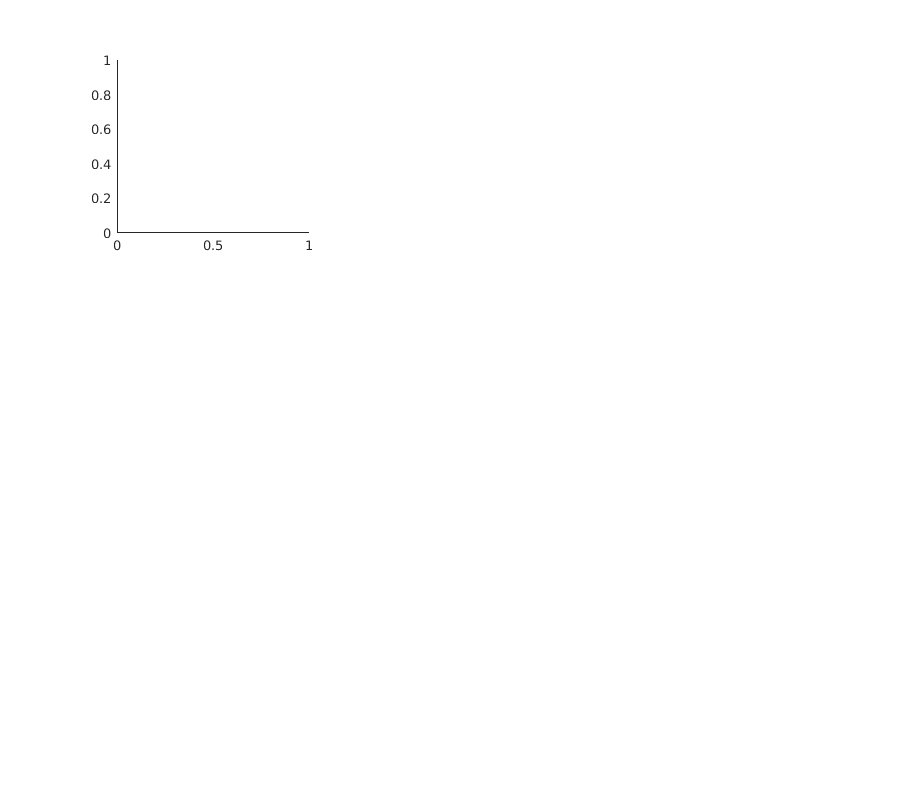

seismogramsEvolution                =   figure('Name',...
    'Model seismograms','NumberTitle','off',...
    'Position',[1000,200,900,800]);

subplot(3,3,1)

Set plot amplitudes at the 9 stations

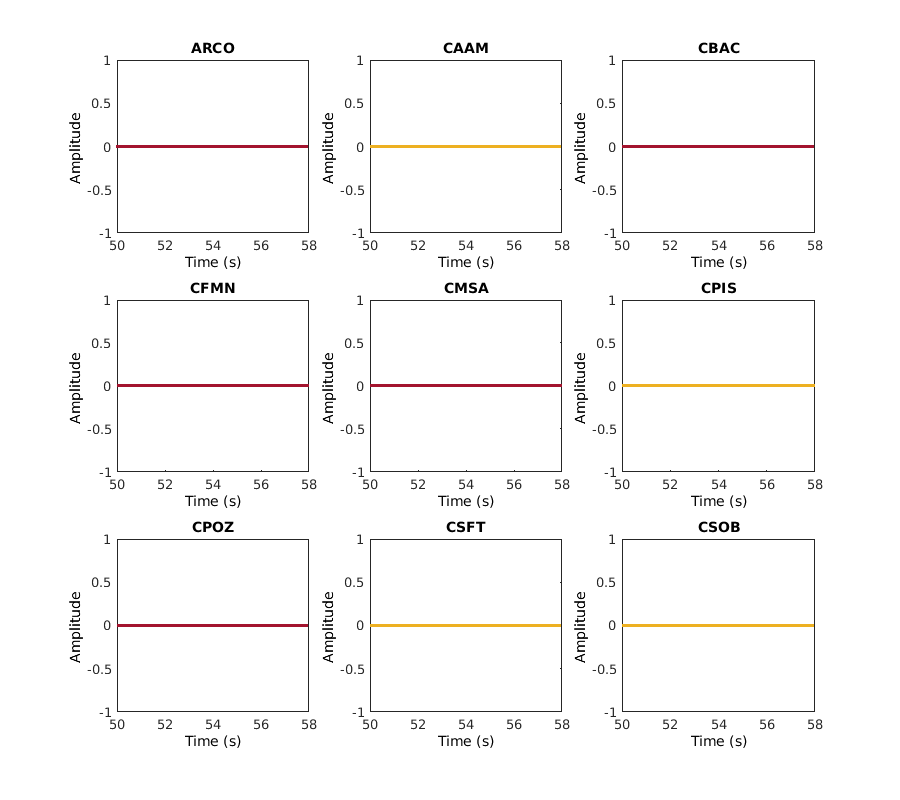

seismogramS1 = plot(Time,AmpTime1,'Color',[0.64,0.08,0.18],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{1})
set(seismogramS1,'xdatasource','Time','ydatasource','AmpTime1')

subplot(3,3,2)
seismogramS2 = plot(Time,AmpTime2,'Color',[0.93,0.69,0.13],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{2})
set(seismogramS2,'xdatasource','Time','ydatasource','AmpTime2')

subplot(3,3,3)
seismogramS3 = plot(Time,AmpTime3,'Color',[0.64,0.08,0.18],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{3})
set(seismogramS3,'xdatasource','Time','ydatasource','AmpTime3')

subplot(3,3,4)
seismogramS4 = plot(Time,AmpTime4,'Color',[0.64,0.08,0.18],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{4})
set(seismogramS4,'xdatasource','Time','ydatasource','AmpTime4')

subplot(3,3,5)
seismogramS5 = plot(Time,AmpTime5,'Color',[0.64,0.08,0.18],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{5})
set(seismogramS5,'xdatasource','Time','ydatasource','AmpTime5')

subplot(3,3,6)
seismogramS6 = plot(Time,AmpTime6,'Color',[0.93,0.69,0.13],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{6})
set(seismogramS6,'xdatasource','Time','ydatasource','AmpTime6')

subplot(3,3,7)
seismogramS7 = plot(Time,AmpTime7,'Color',[0.64,0.08,0.18],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{7})
set(seismogramS7,'xdatasource','Time','ydatasource','AmpTime7')

subplot(3,3,8)
seismogramS8 = plot(Time,AmpTime8,'Color',[0.93,0.69,0.13],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{8})
set(seismogramS8,'xdatasource','Time','ydatasource','AmpTime8')

subplot(3,3,9)
seismogramS9 = plot(Time,AmpTime9,'Color',[0.93,0.69,0.13],'LineWidth',2);
xlabel('Time (s)','FontSize',12,'FontWeight','normal','Color','k')
ylabel('Amplitude ','FontSize',12,'FontWeight','normal','Color','k')
title(namest{9})

set(seismogramS9,'xdatasource','Time','ydatasource','AmpTime9')

## COMPUTATION

Finite Differences weights

x1                                  =   9/(8*dx);
x2                                  =   -1/(24*dx);
z1                                  =   9/(8*dz);
z2                                  =   -1/(24*dz);

Starting time of real seismograms

t                                   =   50;
index                               =   0;
kx                                  =   3:nodesX-2;
kz                                  =   3:nodesZ-2;

Time stepping

tic
for n = 1:numberStep
    t                               =   t+dt;

Absorbing boundaries Horizontal stripes

    u2(1:nab,:)                     =   u2(1:nab,:).*sabTop;
    u2(nodesX-nab+1:nodesX,:)       =...
        u2(nodesX-nab+1:nodesX,:).*sabBottom;

Vertical stripes

    u2(:,1:nab)                     =   u2(:,1:nab).*sabLeft;
    u2(:,nodesZ-nab+1:nodesZ)       =...
        u2(:,nodesZ-nab+1:nodesZ).*sabRight;

Strains Eqs. 9.24 and 9.53

- i-3/2 -> i-2

- i-1/2 -> i-1

- i+1/2 -> i

- i+3/2 -> i+1

    e4                              =...
        z1*(u2(kx,kz)-u2(kx,kz-1))+z2*(u2(kx,kz+1)-u2(kx,kz-2));
    e6                              =...
        x1*(u2(kx,kz)-u2(kx-1,kz))+x2*(u2(kx+1,kz)-u2(kx-2,kz));

Memory variables Eqs. (4.232)4 and 9.54

    f1                              =   2*ts2(kx,kz)-dt;
    f2                              =   2*ts2(kx,kz)+dt;
    ee                              =   e23(kx,kz);
    e23(kx,kz)                      =...
        (2*dt*ts2(kx,kz).*phi2(kx,kz).*e4+f1.*e23(kx,kz))./f2;
    e23(kx,kz)                      =   0.5*(e23(kx,kz)+ee);
    f1                              =   2*ts4(kx,kz)-dt;
    f2                              =   2*ts4(kx,kz)+dt;
    ee                              =   e12(kx,kz);

Eqs. (4.149)6 and 9.54

    e12(kx,kz)                      =...
        (2*dt*ts4(kx,kz).*phi4(kx,kz).*e6+f1.*e12(kx,kz))./f2;
    e12(kx,kz)                      =   0.5*(e12(kx,kz)+ee);

Stresses - Eq. 4.2333

    s4(kx,kz)                       =...
        c44(kx,kz).*(e4+e23(kx,kz))+c46(kx,kz).*e6;
    s6(kx,kz)                       =...
        c66(kx,kz).*(e6+e12(kx,kz))+c46(kx,kz).*e4;

Strains Eqs. 9.24:

- i-3/2 -> i-2

- i-1/2 -> i-1

- i+1/2 -> i

- i+3/2 -> i+1

    ds4                             =...
        z1*(s4(kx,kz+1)-s4(kx,kz))+z2*(s4(kx,kz+2)-s4(kx,kz-1));
    ds6                             =...
        x1*(s6(kx+1,kz)-s6(kx,kz))+x2*(s6(kx+2,kz)-s6(kx-1,kz));

Acceleration

    acc                             =   (ds4+ds6)./rho(kx,kz);

Source - corrected errata

    if n<=nw
        n1                          =   n*2-1;
        source                      =   Amp*f(n1);
    elseif n>nw
        source                      =   0;
    end

Euler equation Eqs. (1.46)1 and 9.52

    u(kx,kz)                        =   2*u2(kx,kz)-u(kx,kz)+dt*dt*acc;
    u(ix,iz)                        =   u(ix,iz)+source;

Update displacement

    uu                              =   u2(kx,kz);
    u2(kx,kz)                       =   u(kx,kz);
    u(kx,kz)                        =   uu;

Seismograms

    AmpTime1(n)                     =   u2(floor(rx(1)),floor(rz(1)));
    AmpTime2(n)                     =   u2(floor(rx(2)),floor(rz(2)));
    AmpTime3(n)                     =   u2(floor(rx(3)),floor(rz(3)));
    AmpTime4(n)                     =   u2(floor(rx(4)),floor(rz(4)));
    AmpTime5(n)                     =   u2(floor(rx(5)),floor(rz(5)));
    AmpTime6(n)                     =   u2(floor(rx(6)),floor(rz(6)));
    AmpTime7(n)                     =   u2(floor(rx(7)),floor(rz(7)));
    AmpTime8(n)                     =   u2(floor(rx(8)),floor(rz(8)));
    AmpTime9(n)                     =   u2(floor(rx(9)),floor(rz(9)));

Plot

    if isequal(mod(n,nFrame),0)
        index                       =   index+1;
        refreshdata(panelWavefield)
        refreshdata(seismogramS1)
        refreshdata(seismogramS2)
        refreshdata(seismogramS3)
        refreshdata(seismogramS4)
        refreshdata(seismogramS5)
        refreshdata(seismogramS6)
        refreshdata(seismogramS7)
        refreshdata(seismogramS8)
        refreshdata(seismogramS9)
        drawnow
        F(index)                    =   getframe(gcf);
        
    end
    
end
toc

Different names for plotting

if chooseModel==1
    label                           =   'Isotropic_1Hz.avi';
    label1                          =   'Isotropic_1Hz.fig';
elseif chooseModel==2
    label                           =   'Anisotropic_1Hz.avi';
    label1                          =   'Anisotropic_1Hz.fig';
elseif chooseModel==3
    label                           =   'Anisotropic_scattering.avi';
    label1                          =   'Anisotropic_scattering.fig';
end

Create Video and Figures

video                               =   VideoWriter(label,'Motion JPEG AVI' );
video.FrameRate                     =   3;
open(video);
writeVideo(video,F);
close(video);
saveas(figureWavefield,label1)
saveas(seismogramsEvolution,strcat(num2str(fSource),'_Modelled'))

## Data to fit

Frequency to filter.

fSource                             =   1;

Lengths to show.

l11                                 =   50;
l22                                 =   58.68;

Names of the files

nmarker0                            =   '151007/*N.sac';
list                                =   dir(nmarker0);
filenames                           =   {list.name}';
filedir                             =   {list.folder}'; 
listasac                            =   strcat(filedir,'/',filenames);
lls                                 =   length(listasac);
[tempis,sismaew,SAChdr]             =   fget_sac(listasac{1});
lsis                                =   length(sismaew);
title1                              =   cell(lls,1);
title2                              =   cell(lls,1);

Get coordinates of the stations

filename = 'stazioni_151007.txt';
delimiterIn = ' ';
headerlinesIn = 0;
A = importdata(filename,delimiterIn,headerlinesIn);
stazioni=A.data;
namest=A.textdata;

nmarker=nmarker0(9);
tu                      =   tukeywin(lsis,0.05);%avoid windowing
window=20;

nmarker2=[nmarker0(9) '- 1 Hz'];
for i=1:lls
    title2(i)=strcat(namest(i), nmarker2);
end

hb=figure('Name','Filtered - 1 Hz',...
    'NumberTitle','off','Position',[1,200,900,800]);


Processing of the files and final figure.

for i=1:lls    

 Load data.

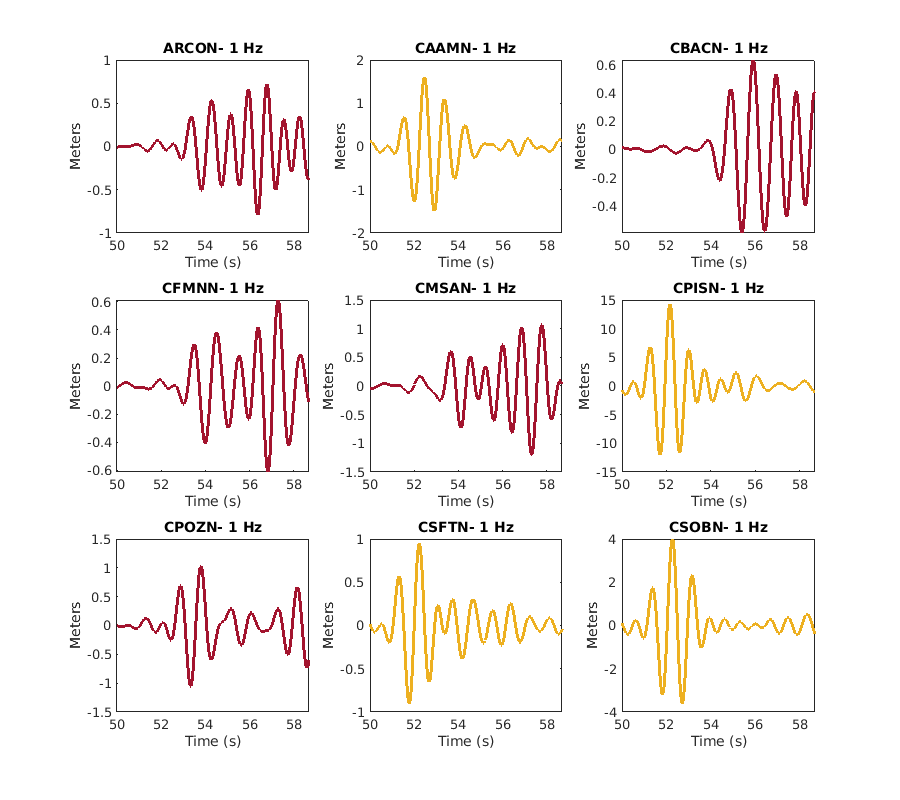

    [tempis,sisma1,SAChdr]=fget_sac(listasac{i});

    srate                       =   1/SAChdr.times.delta;

Creation of filter and application.

    Wn                      =   ([fSource-fSource/3 fSource+fSource/3]/srate*2);
    [z,p,k]                 =   butter(4,Wn,'bandpass');
    [sos,g]                 =   zp2sos(z,p,k);
    sisma2  =   detrend(sisma1/SAChdr.data.scale,1);
    sisma(i,:) = sisma2;
    tsisma         =   tu'.*sisma(i,:);
    fsisma         =   filtfilt(sos,g,tsisma);

Sub-panels for the figure.

subplot(3,3,i)
    switch i
        case {1, 3, 4, 5, 7}
            plot(tempis,fsisma,'Color',[0.64,0.08,0.18],'LineWidth',2);
        case {2, 6, 8, 9}
            plot(tempis,fsisma,'Color',[0.93,0.69,0.13],'LineWidth',2);
    end
    title(title2{i})
    xlim([l11,l22]);
    xlabel('Time (s)'); ylabel('Meters')
end

saveas(hb,strcat(num2str(fSource),'_Data'))